#                                                     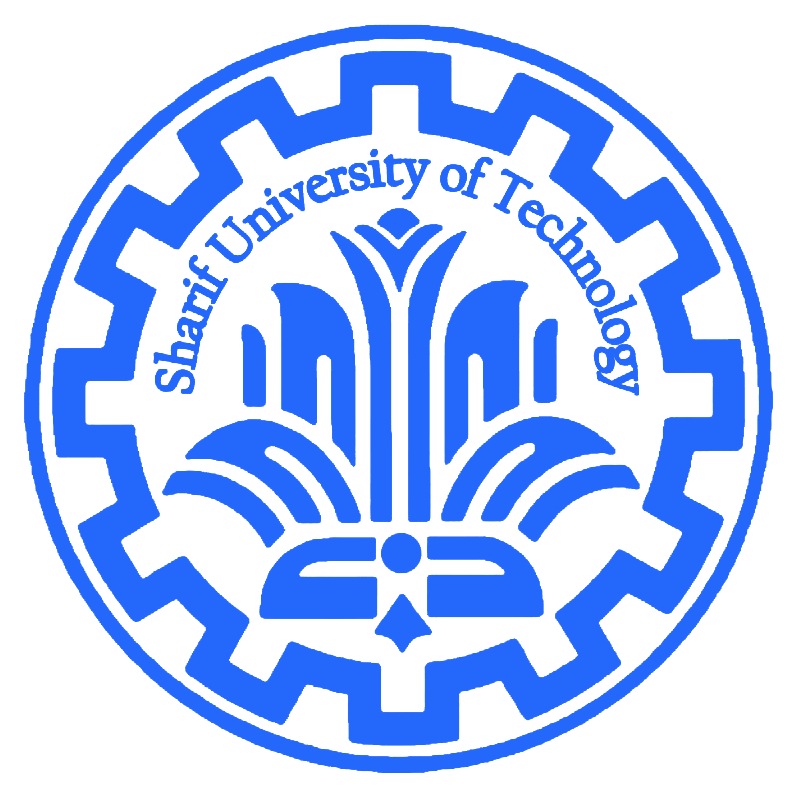        

# 
$$\textbf{Stochastic Processes}
$$


# 
$$\text{Computer Assignment \#1
}
$$


#### 
$$\textit{Masoud Tahmasbi Fard - 402200275
}$$


### 
$$\textbf{Question \#1}$$


**............................................................................................................**

### 
$$\text{Part B}.$$
 

.............................................................................................................

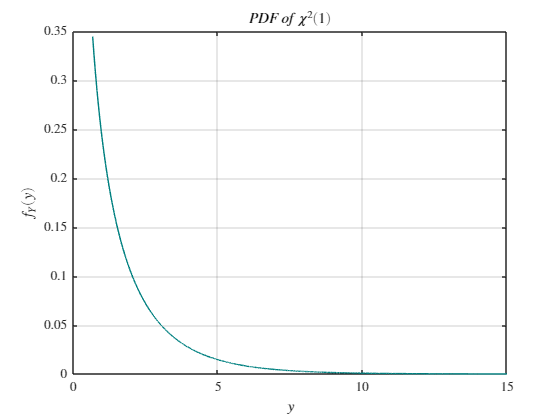

rng(312) % Specify the seed for random number generator
N = 10000;
figure
y = linspace(0.68,15,10000);
f_Y = (1./sqrt(2.*pi.*y)).*(exp(-y./2)); % Theoretically obtained PDF
plot(y,f_Y,'Color','#008080');

% Plotting properties
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$y$','interpreter','latex')
ylabel('$f_Y(y)$','interpreter','latex')
title('$PDF\,of\,\chi^2(1)$','interpreter','latex')
grid on;

### 
$$\text{Part C}.$$
 

.............................................................................................................

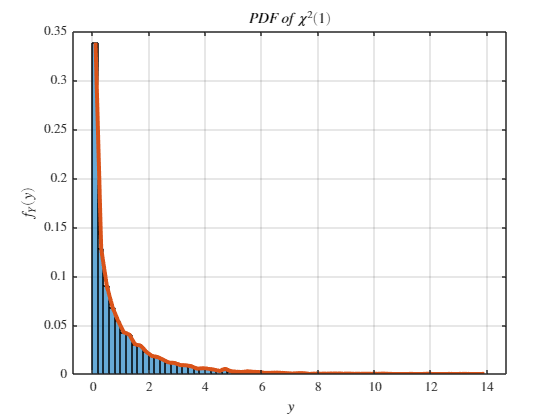

X= randn(N,1).^2; % Generating Chi-Squared distribution

figure
h = histogram(X,'Normalization','probability');
hold on;
[counts, edges] = histcounts(X, 'Normalization','probability');
locs = movmean(edges, 2, 'Endpoints', 'discard'); % Estimating PDF using moving average
plot(locs, counts, 'LineWidth', 3);

% Plotting properties
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$y$','interpreter','latex')
ylabel('$f_Y(y)$','interpreter','latex')
title('$PDF\,of\,\chi^2(1)$','interpreter','latex')
grid on;

### 
$$\textbf{Question \#2}$$


**............................................................................................................**

### 
$$\text{Part A}.$$
 

.............................................................................................................

X = sqrt(5)*randn(10000,1);

### 
$$\text{Part B}.$$
 

.............................................................................................................

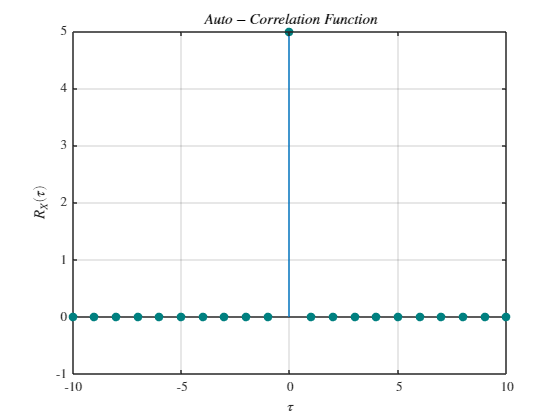

num_iteration = 5000;
num_sample = 10000;
max_tav = 10;

Rx_avg = zeros(2*max_tav+1,1);
for i = 1:num_iteration % Calculating average values
    X = sqrt(5)*randn(num_sample,1);
    [Rx,tau] = xcorr(X,X,max_tav); % Auto correlation function
    Rx_avg = Rx_avg + Rx;
end
Rx_avg = Rx_avg/num_iteration/num_sample;

figure
stem(tau,Rx_avg,'filled', 'MarkerFaceColor','#008080',...
 'MarkerEdgeColor','#008080')

% Plotting properties
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\tau$','interpreter','latex')
ylabel('$R_X(\tau)$','interpreter','latex')
title('$Auto-Correlation\;Function$','interpreter','latex')
grid on;

### 
$$\text{Part C}.$$
 

.............................................................................................................

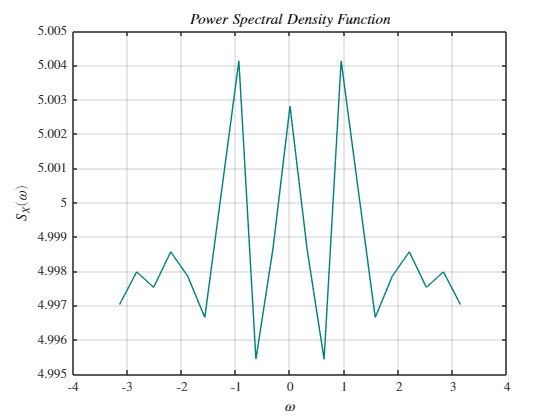

L = numel(Rx_avg);                                               
Sx = fftshift(fft(Rx_avg)); % Fourier Transform
freq = linspace(-1, 1, L)*pi;
idx = 1:numel(freq); 

figure
plot(freq, abs(Sx(idx)),'Color','#008080')
% Plotting properties
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
ylabel('$S_X(\omega)$','interpreter','latex')
title('$Power\;Spectral\;Density\;Function$','interpreter','latex')
grid on;

mean(abs(Sx(idx)))

ans = 4.9986

### 
$$\textbf{Question \#3}$$


**............................................................................................................**

### 
$$\text{Part B}.$$
 

.............................................................................................................

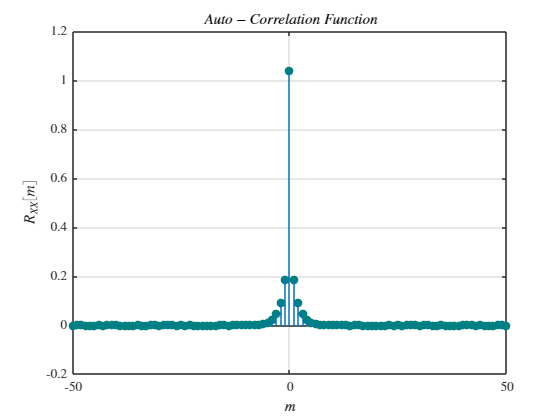

A = [1 -1/2];
B = [1 -1/3];
num_iteration = 10000;
max_m = 50;

R_xx_avg = zeros(2*max_m+1,1);
R_xv_avg = zeros(2*max_m+1,1);

for i = 1:num_iteration
    v = randn(num_sample,1);
    x = filter(B,A,v);    
    [Rxx,m_xx] = xcorr(x,x,max_m); % Auto correlation function
    R_xx_avg = R_xx_avg + Rxx;

    [Rxv,m_xv] = xcorr(x,v,max_m); % Cross correlation function
    R_xv_avg = R_xv_avg + Rxv;
end
R_xx_avg = R_xx_avg/num_iteration/num_sample; % Average Value
R_xv_avg = R_xv_avg/num_iteration/num_sample; % Average Value

figure
stem(m_xx,R_xx_avg,'filled', 'MarkerFaceColor','#008080',...
 'MarkerEdgeColor','#008080')

% Plotting properties
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$m$','interpreter','latex')
ylabel('$R_{XX}\left[m\right]$','interpreter','latex')
title('$Auto-Correlation\;Function$','interpreter','latex')
grid on;

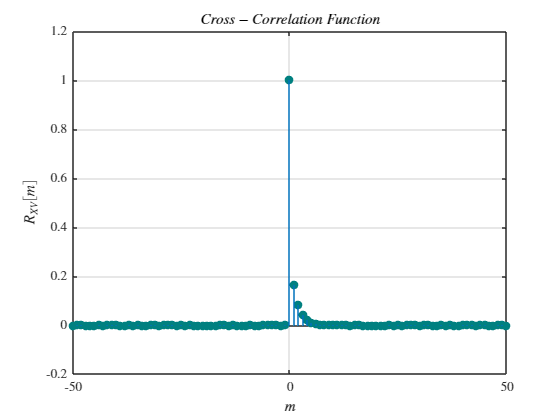

figure
stem(m_xv,R_xv_avg,'filled', 'MarkerFaceColor','#008080',...
 'MarkerEdgeColor','#008080')

% Plotting properties
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$m$','interpreter','latex')
ylabel('$R_{XV}\left[m\right]$','interpreter','latex')
title('$Cross-Correlation\;Function$','interpreter','latex')
grid on;

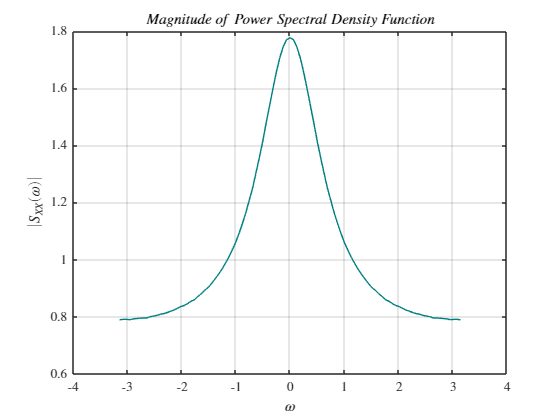

L = numel(R_xx_avg);                                               
Sxx = fftshift(fft(R_xx_avg)); % Fourier Transform
freq = linspace(-1, 1, L)*pi;
idx = 1:numel(freq); 

figure
plot(freq, abs(Sxx(idx)),'Color','#008080')
% Plotting properties
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
ylabel('$|S_{XX}(\omega)|$','interpreter','latex')
title('$Magnitude\;of\;Power\;Spectral\;Density\;Function$','interpreter','latex')
grid on;

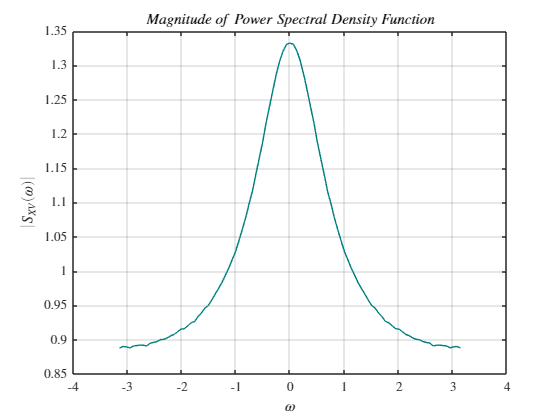

L = numel(R_xv_avg);                                               
Sxv = fftshift(fft(R_xv_avg)); % Fourier Transform
freq = linspace(-1, 1, L)*pi;
idx = 1:numel(freq); 

figure
plot(freq, abs(Sxv(idx)),'Color','#008080')
% Plotting properties
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
ylabel('$|S_{XV}(\omega)|$','interpreter','latex')
title('$Magnitude\;of\;Power\;Spectral\;Density\;Function$','interpreter','latex')
grid on;

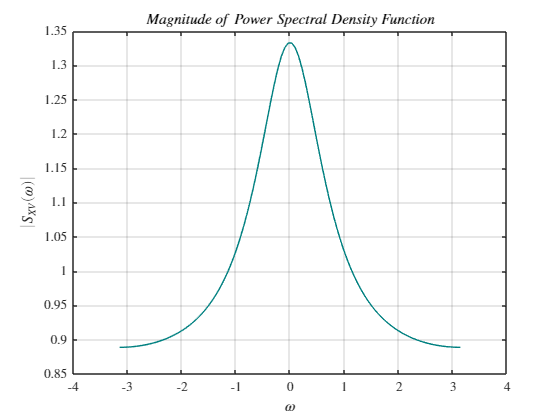

w = linspace(-pi,pi,100);
z = exp(1i.*w);
figure
plot(w,abs( ( 1-(1/3).*z )./( 1-0.5.*z ) ),'Color','#008080')
% Plotting properties
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
ylabel('$|S_{XV}(\omega)|$','interpreter','latex')
title('$Magnitude\;of\;Power\;Spectral\;Density\;Function$','interpreter','latex')
grid on;

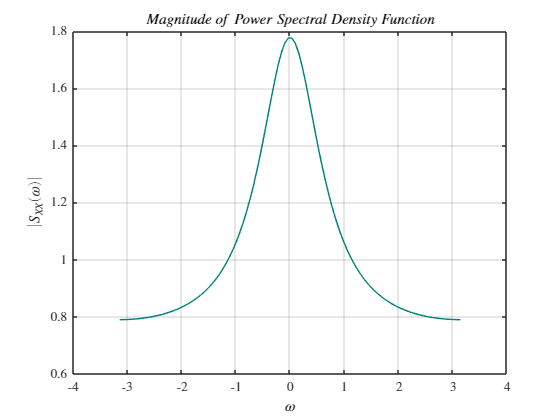

w = linspace(-pi,pi,100);
figure
plot(w,abs( ( 1- (1/3).*z.^(-1) - (1/3).*z +(1/9) )./( ( 1- (1/2).*z.^(-1) - (1/2).*z +(1/4) ) )),'Color','#008080')
% Plotting properties
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$\omega$','interpreter','latex')
ylabel('$|S_{XX}(\omega)|$','interpreter','latex')
title('$Magnitude\;of\;Power\;Spectral\;Density\;Function$','interpreter','latex')
grid on;

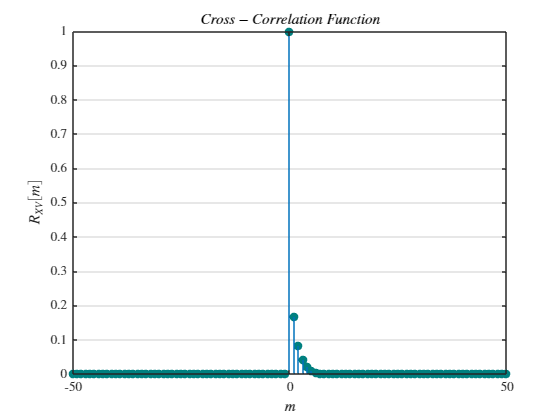

oldparam = sympref('HeavisideAtOrigin',1); % u[0] = 1

m = linspace(-max_m,max_m,2*max_m+1);
Rxv_th = (1/2).^(m).*( heaviside(m) -(2/3).*heaviside(m-1) );


figure
stem(m,Rxv_th,'filled', 'MarkerFaceColor','#008080',...
 'MarkerEdgeColor','#008080')

% Plotting properties
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$m$','interpreter','latex')
ylabel('$R_{XV}\left[m\right]$','interpreter','latex')
title('$Cross-Correlation\;Function$','interpreter','latex')
grid on;

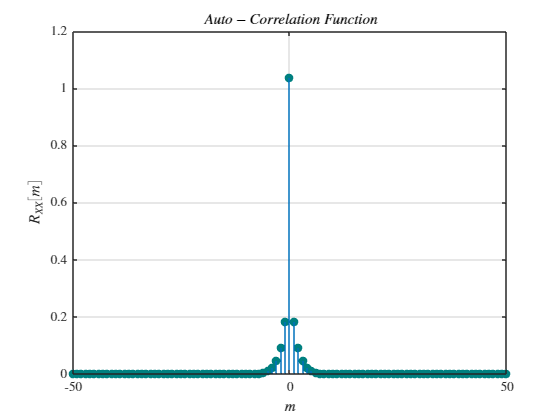

m = linspace(-max_m,max_m,2*max_m+1);
Rxx_th = (10/27).*(2).^(m).*heaviside(-m-1) +(1/27).*(1/2).^(m).*heaviside(m) + (1/6).*(1/2).^(m-1).*heaviside(m-1);
Rxx_th(max_m+1) = Rxx_th(max_m+1) + 1; % delta at m = 0

figure
stem(m,Rxx_th,'filled', 'MarkerFaceColor','#008080',...
 'MarkerEdgeColor','#008080')

% Plotting properties
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
xlabel('$m$','interpreter','latex')
ylabel('$R_{XX}\left[m\right]$','interpreter','latex')
title('$Auto-Correlation\;Function$','interpreter','latex')
grid on;